BME3053C Computer Applications Project

Group Members: Gionela Lepage, Trey Chesser, Fabiana Amato

Course: BME 3053C Computer Applications for BME

Term: Fall 2021

J. Crayton Pruitt Family Department of Biomedical Engineering

University of Florida

Step 1: Read the audio file and plot it in the time domain

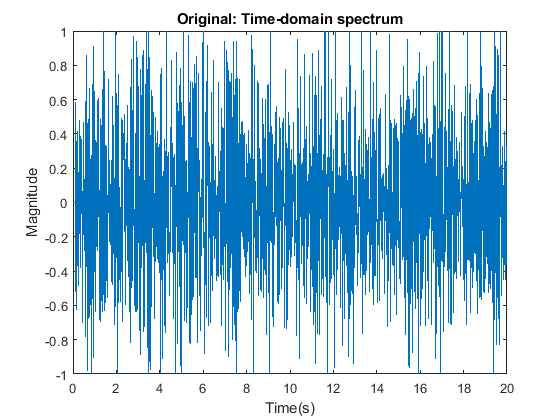

clc;clear;close all
[y, Fs] = audioread("COPD_patient_1.wav");
sound(y,Fs);
L=length(y);
N=size(y,1);
T=1/Fs;
t = (0:L-1)*T;
plot(t,y); 
title('Original: Time-domain spectrum')
xlabel('Time(s)');ylabel('Magnitude')

Step 2: Filter the signal using the function `bandpass` and plot it in the time domain

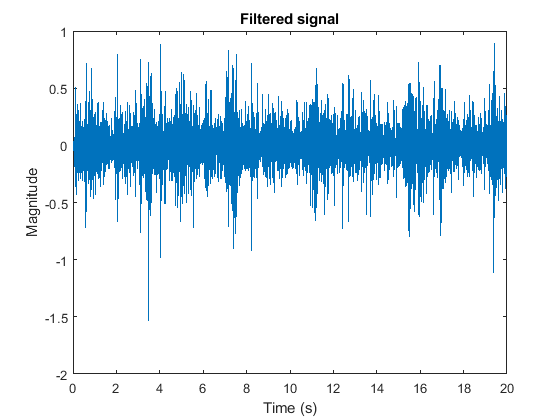

%bandpass filter
y2=bandpass(y,[20 200],Fs);
figure(1)
plot(t,y2)
title('Filtered signal')
xlabel('Time (s)'); ylabel('Magnitude')

Step 3: Convert the signal from the time domain into the frequency domain by computing a Fuorier Transform using the function `fft, `then plot it against the frequency. Finally, compute the power spectra of the filtered signal using the function `periodogram `plot it against time.

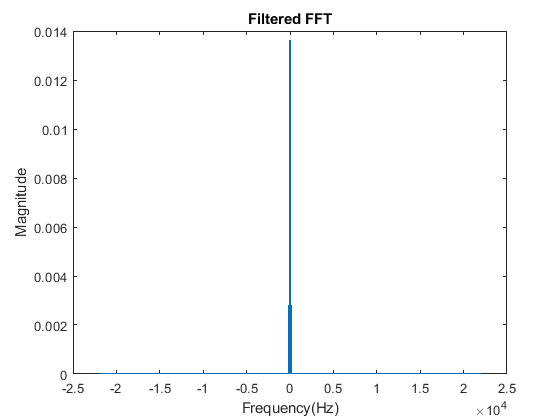

%FFT
df=Fs/N;
w=(-(N/2):(N/2)-1)*df;
Y=fft(y2)/N;
Y=fftshift(Y);
figure; plot(w,abs(Y))
title('Filtered FFT')
xlabel('Frequency(Hz)'); ylabel('Magnitude')

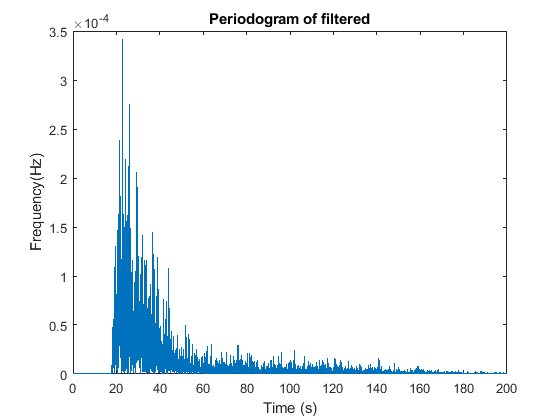


%periodogram
[P1,f1]=periodogram(y2,[],[],Fs,'Power');
figure(3)
plot(f1,P1)
xlim([0 200])
title('Periodogram of filtered')
xlabel('Time (s)');ylabel('Frequency(Hz)')

Step 4: Compute the mean of the absolute value of the filtered signal to apply the apporiate threshold. When the mean is greater than 3e-6, diagnose the patient with COPD

F=abs(Y);
g=mean(F);

if g>3e-6
    fprintf('The patient has COPD')
else
    fprintf('The patient is healthy')
end

The patient has COPD